# Robotics 2 - Final exam - June 11, 2018

## Exercise 1

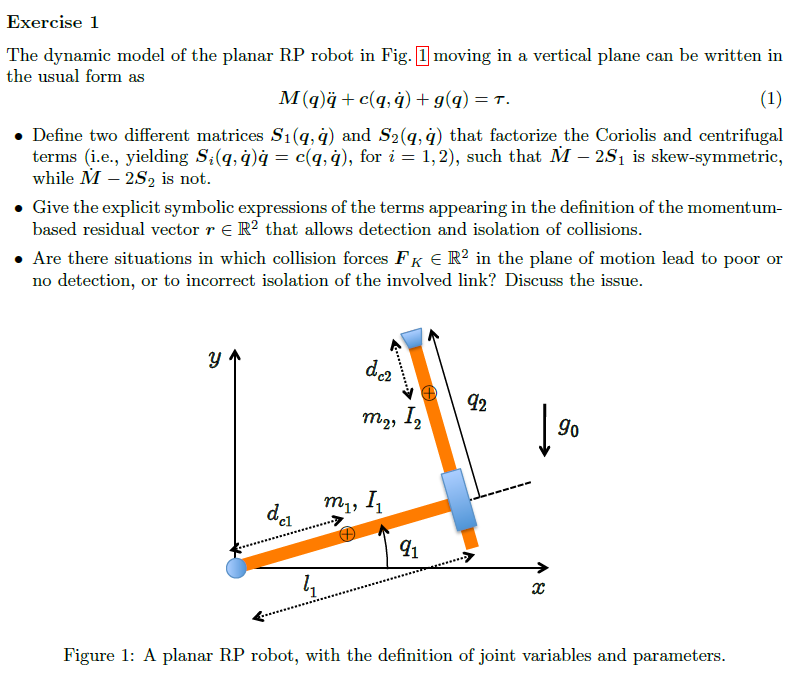

% % This part is isolated from previous sectionclear;clc
% clear all, close all, clc;
% % syms k q1(t) q2(t) q3(t)
% sigmaD = [0,1];
% n = length(sigmaD);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,-g0,0]';

s

% R2Robot=['rp';'xy';sigmaD]
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
%
% z.g=g;
%
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1%2=with DH table
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% % z.opt_expr={[l(1)+q(2)],[q(2)]};
% % z.rcdefined=true;
% z.prismatic_CoM_method(2)=2;

%
%
% % xyonly=true
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)
% % VarShortRobot.M
% % angle_desired=[0,0]
% % l(1)=0
% [Pc,vc,w,T,Ti,M] = getGenericPC2(z)
% % [C,cac,Csubs,S] = getCs(M,q,q_dot);

% M

Viscouz terms

% % F_v=sym('F_v',[n,1],'real').*eye(n)

## gravity computation

% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l, m, dc, g, isMotor)
% U{:}

## get dinamyc paramters

% % [Msubs, dynamicParameters, aM] = getDynamicParameters(M,q,[])
% % [Gsubs, dynamicParametersG, aG] = getDynamicParameters(g_q,q,[g0],1)
% % [All, dynamicParamsReturn, a]= getDynamicParameters([M,diag(g_q),F_v],q,[q_dot.',g0],2)

% [C,cac,Csubs,S1] = getCs(M,q,q_dot)
% % u =simplify( M*q_ddot + cac+g_q+F_v*q_dot)
% % [usubs, dynamicParametersu, au] = getDynamicParameters(u,q,[])
% %
% % Msubs = All(:,1:n)
% % gSubs = diag(All(:,n+1:2*n))
% % FSubs = All(:,2*n+1:end)
% [Md,Mtd,qt]  = getM_dot2(M, q, q_dot)

% [S0,S_] = getGenericS0(q,q_dot)
% S0_=subs(S0{2},S_(:,1)',[q_dot(2),0]);
%
% S2=S1+S0_
% S1
% Md
% simplify(Md-2*S1)
% simplify(Md-2*S2)

% % u_subs = Msubs*q_ddot + gSubs +FSubs*q_dot

collisions

defining collisions

% %
% % collide1=
% rho=sym('rho',[2,1],'real')
% F_0=sym('F_0','real')
% z.collides=[struct('F',F_0*[cos(q(1)),sin(q(1)),0]' ,'joint',1,'F_pos',rho(1)),
% %             struct('F',[0,-1,0]' ,'joint',1,'F_pos',l(1)),
% %             struct('F',[0, 1,0]' ,'joint',2,'F_pos',l(2)/2)
%             ];
% z.collides(1)

computing colissions

% z.prismatic_CoM_method=[1,2]
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans,zout] = getCollisions(z)

% zout.g_q
% zout.S
% zout.J_c_collisions_{:}
% zout.vc_collisions
% zout.Vc_T_dot_Fk
% zout.Tau_c
% zout.r
% zout.p_r
% zout.to_integrate
% % vc_=subs(vc,q,q_)
% % [C,cac,Csubs,S] = getCs(M,q,q_dot);
%

## when the forces over link 2 won't be detected or misdetected?

% %
% % collide1=
% rho=sym('rho',[2,1],'real')
% F_0=sym('F_0','real')
% z.collides=[struct('F',F_0*[cos(q(1)),sin(q(1)),0]' ,'joint',2,'F_pos',rho(2)),
% %             struct('F',[0,-1,0]' ,'joint',1,'F_pos',l(1)),
% %             struct('F',[0, 1,0]' ,'joint',2,'F_pos',l(2)/2)
%             ];
% z.collides(1)

computing colissions

% z.prismatic_CoM_method=[1,2]
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans,zout] = getCollisions(z)

% zout.g_q
% zout.S
% zout.J_c_collisions_{:}
% zout.vc_collisions
% zout.Vc_T_dot_Fk
% zout.Tau_c
% zout.r
% zout.p_r
% zout.to_integrate
% % vc_=subs(vc,q,q_)
% % [C,cac,Csubs,S] = getCs(M,q,q_dot);
% zout.Pc_collisions

%
% % collide1=
% rho=sym('rho',[2,1],'real')
% F_0=sym('F_0','real')
% z.collides=[struct('F',F_0*zout.Pc_collisions ,'joint',2,'F_pos',rho(2)),
% %             struct('F',[0,-1,0]' ,'joint',1,'F_pos',l(1)),
% %             struct('F',[0, 1,0]' ,'joint',2,'F_pos',l(2)/2)
%             ];
% z.collides(1)

computing colissions

% z.prismatic_CoM_method=[1,2]
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans,zout2] = getCollisions(z)

% zout2.g_q
% zout2.S
% zout2.J_c_collisions_{:}
% zout2.vc_collisions
% zout2.Vc_T_dot_Fk
% zout2.Tau_c
% zout2.r
% zout2.p_r
% zout2.to_integrate
% % vc_=subs(vc,q,q_)
% % [C,cac,Csubs,S] = getCs(M,q,q_dot);

## Exercise 2

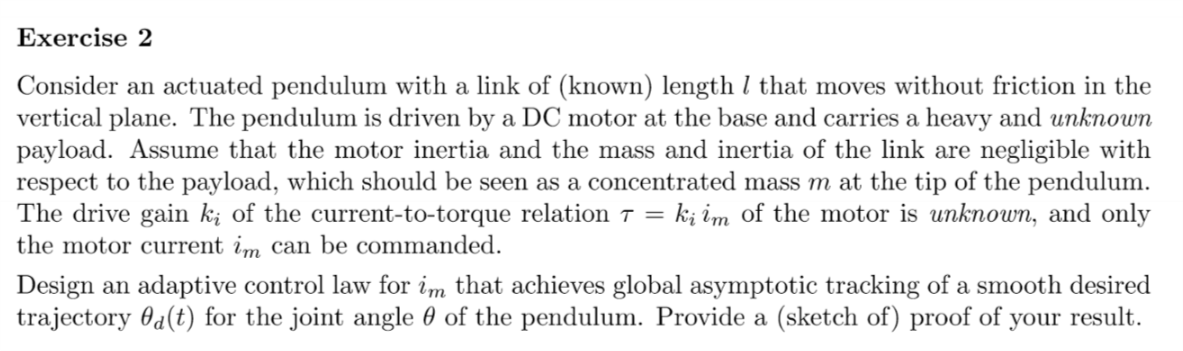

% % clear; clc;
% % sigma = [0]
% % n = 1
% % syms q qd m l d I g
% % g0 = [0 g 0].'
% % dhTable = [0 l 0 q]

% % getKEwithJacobian(dhTable,sigma,q,qd,l,m,0,d,0)
% % Gravity(dhTable,g0,m,d,q)

% % syms m d ks s
% % ff = m*s^2 +d*s+ks
% % solve(ff,s)

clear;clc
%
% % syms k q1(t) q2(t) q3(t)
sigma = [0];
n = length(sigma);
% t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');

q = sym('theta_', [n 1],'real');
q_dot = sym('theta_dot_', [n 1],'real');
q_ddot = sym('theta_ddot_', [n 1],'real');

%
dc = sym('dc_', [n 1],'real');
% k = sym('k', [n 1],'real');
l = sym('l_', [n 1],'real');
m = sym('m_', [n 1],'real');
I = sym('I_', [n 1],'real');

% motor definitions
% q_m = sym('q_m_', [n 1],'real');
% q_dot_m = sym('q_dot_m_', [n 1],'real');
% q_ddot_m = sym('q_ddot_m_', [n 1],'real');

q_m = sym('theta_m_', [n 1],'real');
q_dot_m = sym('theta_dot_m_', [n 1],'real');
q_ddot_m = sym('theta_ddot_m_', [n 1],'real');

%desired values

% q_d = sym('q_d_', [n 1],'real');
% q_dot_d = sym('q_dot_d_', [n 1],'real');
% q_ddot_d = sym('q_ddot_d_', [n 1],'real');

q_d = sym('theta_d_', [n 1],'real');
q_dot_d = sym('theta_dot_d_', [n 1],'real');
q_ddot_d = sym('theta_ddot_d_', [n 1],'real');


%
% dc = sym('dc_', [n 1],'real');

% l = sym('l_', [n 1],'real');
m_m = sym('m_m_', [n 1],'real');
I_m = sym('I_m_', [n 1],'real');


alpha_angle=sym('alpha','real')

$$alpha\_angle = \alpha$$

g0 = sym('g0','real');
g=[0,g0,0]';

defining z struct

R2Robot=['r';'y';sigma]

R2Robot = 3×1 char array
    'r'
    'y'
    ' '


z = Gen_param(n);

z = struct with fields:
        sigmaD: []
             l: []
            l_: []
             q: []
         q_dot: []
            q_: []
        q_dot_: []
            dc: []
             m: []
             I: {}
       methodD: 1
       dhTable: []
    firstParam: 'alpha'
             t: [1×1 sym]


z.vartoderivate='theta';

z.g0=g0;
z.g=g;
z.sigmaD=R2Robot;
z.l=l;
z.q=q;
z.q_dot=q_dot;
z.q_ddot=q_ddot;
z.m=m;
z.I=I;

z.q_m=q_m;
z.q_dot_m=q_dot_m;
z.q_ddot_m=q_ddot_m;
z.m_m=m_m;
z.I_m=I_m;

z.q_d=q_d;
z.q_dot_d=q_dot_d;

z.dc=dc;
z.methodD=1;
% z.dhTable=[]
z.firstParam='alpha';
% z.rc=[];
% z.movingframes=[];
z.angle_=sym(zeros(1,n));
l_0=sym('l','real')

$$l\_0 = l$$

% z.opt_expr={l,[l_0,l_0,l_0,l_0]'};%not necessary

% z.rcdefined=true;

z.ismotor=false;%% important!!!!
z.motoronly=false;
z.vartoderivate="theta";

## axis offset

%
% h=sym('h','real')
% %x,y,z
% z.xyx_offset=sym(zeros(3,n));
% z.xyx_offset(:,1)=[0,h,0]'%

% %Global q reference?
% % clear
% % z.q_global
% z.global_q_reference=true
% if(z.global_q_reference)
%     [z.q_global,z.q_dot_global]=convert_local2global_q(z.q,z.q_dot,z.sigmaD)
% end



% xyonly=true
% [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)
% VarShortRobot.M
% angle_desired=[0,0]
% l(1)=0
% [Pc,vc,w,T,Ti,M] = getGenericPC2(z)
% [C,cac,Csubs,S] = getCs(M,q,q_dot);
pendulum = pendulum_model(z)

replacing inertias to zero!!!!!!!!!!!


rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×1 char]
                       l: [1×1 sym]
                      l_: []
                       q: [1×1 sym]
                   q_dot: [1×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [1×1 sym]
                       m: [1×1 sym]
                       I: [1×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 1
                  angle_: [1×1 sym]
               rcdefined: 1
                opt_expr: {[2×1 sym]  [2×1 sym]}
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: 1
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 is

si falla aquí está el error
method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{{l_{1}}^{2}\,m_{1}\,{{\dot{\theta }}_{1}}^{2}}{2}$$

$$To\_derive = \left(\begin{array}{c} -l_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\\ -l_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\\ 0 \end{array}\right)$$

$$q\_t = \theta_{1}\left(t\right)$$

z_derivated = struct with fields:
    dot_t: [3×1 sym]


z_derivated = struct with fields:
     dot_t: [3×1 sym]
    ddot_t: [3×1 sym]


z_derivated = struct with fields:
     dot_t: [3×1 sym]
    ddot_t: [3×1 sym]
    tdot_t: [3×1 sym]


z_derivated = struct with fields:
        dot_t: [3×1 sym]
       ddot_t: [3×1 sym]
       tdot_t: [3×1 sym]
          dot: [3×1 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} \theta_{1} & {\dot{\theta }}_{1} & {\ddot{\theta }}_{1} & {\dddot{\theta }}_{1} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [3×1 sym]
       ddot_t: [3×1 sym]
       tdot_t: [3×1 sym]
          dot: [3×1 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [3×1 sym]
        ddot_t: [3×1 sym]
        tdot_t: [3×1 sym]
           dot: [3×1 sym]
     dot_short: []
          ddot: [3×1 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} \theta_{1} & {\dot{\theta }}_{1} & {\ddot{\theta }}_{1} & {\dddot{\theta }}_{1} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×1 sym]
        ddot_t: [3×1 sym]
        tdot_t: [3×1 sym]
           dot: [3×1 sym]
     dot_short: []
          ddot: [3×1 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [3×1 sym]
        ddot_t: [3×1 sym]
        tdot_t: [3×1 sym]
           dot: [3×1 sym]
     dot_short: []
          ddot: [3×1 sym]
    ddot_short: []
          tdot: [3×1 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} \theta_{1} & {\dot{\theta }}_{1} & {\ddot{\theta }}_{1} & {\dddot{\theta }}_{1} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×1 sym]
        ddot_t: [3×1 sym]
        tdot_t: [3×1 sym]
           dot: [3×1 sym]
     dot_short: []
          ddot: [3×1 sym]
    ddot_short: []
          tdot: [3×1 sym]
    tdot_short: []


$$Pc = \left(\begin{array}{c} -l_{1}\,\sin\left(\theta_{1}\right)\\ l_{1}\,\cos\left(\theta_{1}\right)\\ 0 \end{array}\right)$$

$$vc = \left(\begin{array}{c} -l_{1}\,{\dot{\theta }}_{1}\,\cos\left(\theta_{1}\right)\\ -l_{1}\,{\dot{\theta }}_{1}\,\sin\left(\theta_{1}\right)\\ 0 \end{array}\right)$$

$$w = \left(\begin{array}{c} 0\\ 0\\ {\dot{\theta }}_{1} \end{array}\right)$$

$$T = \frac{{l_{1}}^{2}\,m_{1}\,{{\dot{\theta }}_{1}}^{2}}{2}$$

$$Ti = \frac{{l_{1}}^{2}\,m_{1}\,{{\dot{\theta }}_{1}}^{2}}{2}$$

$$M = {l_{1}}^{2}\,m_{1}$$

VarShortRobot = struct with fields:
    Pc: [3×1 sym]
    vc: [3×1 sym]
     w: [3×1 sym]
     T: [1×1 sym]
    Ti: [1×1 sym]
     M: [1×1 sym]


pendulum = struct with fields:
                 TTotal: [4×4 sym]
                PTotali: [3×1 sym]
               TPartial: {[4×4 sym]}
                 RTotal: [3×3 sym]
               RPartial: {[3×3 sym]}
                 PTotal: [3×1 sym]
        Jacobian_PTotal: [3×1 sym]
    Jacobian_dot_PTotal: [3×1 sym]
               PPartial: {[3×1 sym]}
                     Pc: [3×1 sym]
                RTotali: {[3×3 sym]}
           ThetaPartial: [1×1 sym]
             ThetaTotal: [1×1 sym]
                     vc: [3×1 sym]
                      w: [3×1 sym]
                      T: [1×1 sym]
                     Ti: [1×1 sym]
                      M: [1×1 sym]


isMotor = logical
   0


*** Computation of Potential Energy (Jacobian-based method) 


$$qall\_sincos\_comb = \left(\begin{array}{cc} \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) \end{array}\right)$$

$$PE = -g_{0}\,l_{1}\,m_{1}\,\cos\left(\theta_{1}\right)$$

$$PE\_short = -g_{0}\,l_{1}\,m_{1}\,\cos\left(\theta_{1}\right)$$

$$g\_q\_short = g_{0}\,l_{1}\,m_{1}\,\sin\left(\theta_{1}\right)$$

>> Getting dynamic coefficients. Might take a while...
Only one term in the list of terms


$$paramscell2 = \left(\begin{array}{cc} {l_{1}}^{2} & m_{1} \end{array}\right)$$

MSubs second iteration (before re-replacement)


$$Msubs = {\mathrm{aa}}_{1}$$

si falla uncomment this line verify  una lineas arriba


pendulum = struct with fields:
                 TTotal: [4×4 sym]
                PTotali: [3×1 sym]
               TPartial: {[4×4 sym]}
                 RTotal: [3×3 sym]
               RPartial: {[3×3 sym]}
                 PTotal: [3×1 sym]
        Jacobian_PTotal: [3×1 sym]
    Jacobian_dot_PTotal: [3×1 sym]
               PPartial: {[3×1 sym]}
                     Pc: [3×1 sym]
                RTotali: {[3×3 sym]}
           ThetaPartial: [1×1 sym]
             ThetaTotal: [1×1 sym]
                     vc: [3×1 sym]
                      w: [3×1 sym]
                      T: [1×1 sym]
                     Ti: [1×1 sym]
                      M: [1×1 sym]
                    g_q: [1×1 sym]
                     PE: [1×1 sym]
                      U: {[1×1 sym]}
              g_q_short: [1×1 sym]
               PE_short: [1×1 sym]
                    tau: [1×1 sym]
                  Msubs: [1×1 sym]
     dynamicParametersM: [1×1 sym]
                     aM: [1×1 sym]


pendulum = struct with fields:
                 TTotal: [4×4 sym]
                PTotali: [3×1 sym]
               TPartial: {[4×4 sym]}
                 RTotal: [3×3 sym]
               RPartial: {[3×3 sym]}
                 PTotal: [3×1 sym]
        Jacobian_PTotal: [3×1 sym]
    Jacobian_dot_PTotal: [3×1 sym]
               PPartial: {[3×1 sym]}
                     Pc: [3×1 sym]
                RTotali: {[3×3 sym]}
           ThetaPartial: [1×1 sym]
             ThetaTotal: [1×1 sym]
                     vc: [3×1 sym]
                      w: [3×1 sym]
                      T: [1×1 sym]
                     Ti: [1×1 sym]
                      M: [1×1 sym]
                    g_q: [1×1 sym]
                     PE: [1×1 sym]
                      U: {[1×1 sym]}
              g_q_short: [1×1 sym]
               PE_short: [1×1 sym]
                    tau: [1×1 sym]
                  Msubs: [1×1 sym]
     dynamicParametersM: [1×1 sym]
                     aM: [1×1 sym]


pendulum = struct with fields:
                 TTotal: [4×4 sym]
                PTotali: [3×1 sym]
               TPartial: {[4×4 sym]}
                 RTotal: [3×3 sym]
               RPartial: {[3×3 sym]}
                 PTotal: [3×1 sym]
        Jacobian_PTotal: [3×1 sym]
    Jacobian_dot_PTotal: [3×1 sym]
               PPartial: {[3×1 sym]}
                     Pc: [3×1 sym]
                RTotali: {[3×3 sym]}
           ThetaPartial: [1×1 sym]
             ThetaTotal: [1×1 sym]
                     vc: [3×1 sym]
                      w: [3×1 sym]
                      T: [1×1 sym]
                     Ti: [1×1 sym]
                      M: [1×1 sym]
                    g_q: [1×1 sym]
                     PE: [1×1 sym]
                      U: {[1×1 sym]}
              g_q_short: [1×1 sym]
               PE_short: [1×1 sym]
                    tau: [1×1 sym]
                  Msubs: [1×1 sym]
     dynamicParametersM: [1×1 sym]
                     aM: [1×1 sym]


>> Getting dynamic coefficients. Might take a while...
Only one term in the list of terms


$$paramscell2 = \left(\begin{array}{ccc} g_{0} & l_{1} & m_{1} \end{array}\right)$$

MSubs second iteration (before re-replacement)


$$Msubs = {\mathrm{aa}}_{1}\,\sin\left(\theta_{1}\right)$$

si falla uncomment this line verify  una lineas arriba


pendulum = struct with fields:
                  TTotal: [4×4 sym]
                 PTotali: [3×1 sym]
                TPartial: {[4×4 sym]}
                  RTotal: [3×3 sym]
                RPartial: {[3×3 sym]}
                  PTotal: [3×1 sym]
         Jacobian_PTotal: [3×1 sym]
     Jacobian_dot_PTotal: [3×1 sym]
                PPartial: {[3×1 sym]}
                      Pc: [3×1 sym]
                 RTotali: {[3×3 sym]}
            ThetaPartial: [1×1 sym]
              ThetaTotal: [1×1 sym]
                      vc: [3×1 sym]
                       w: [3×1 sym]
                       T: [1×1 sym]
                      Ti: [1×1 sym]
                       M: [1×1 sym]
                     g_q: [1×1 sym]
                      PE: [1×1 sym]
                       U: {[1×1 sym]}
               g_q_short: [1×1 sym]
                PE_short: [1×1 sym]
                     tau: [1×1 sym]
                   Msubs: [1×1 sym]
      dynamicParametersM: [1×1 sym]
                      a

pendulum = struct with fields:
                  TTotal: [4×4 sym]
                 PTotali: [3×1 sym]
                TPartial: {[4×4 sym]}
                  RTotal: [3×3 sym]
                RPartial: {[3×3 sym]}
                  PTotal: [3×1 sym]
         Jacobian_PTotal: [3×1 sym]
     Jacobian_dot_PTotal: [3×1 sym]
                PPartial: {[3×1 sym]}
                      Pc: [3×1 sym]
                 RTotali: {[3×3 sym]}
            ThetaPartial: [1×1 sym]
              ThetaTotal: [1×1 sym]
                      vc: [3×1 sym]
                       w: [3×1 sym]
                       T: [1×1 sym]
                      Ti: [1×1 sym]
                       M: [1×1 sym]
                     g_q: [1×1 sym]
                      PE: [1×1 sym]
                       U: {[1×1 sym]}
               g_q_short: [1×1 sym]
                PE_short: [1×1 sym]
                     tau: [1×1 sym]
                   Msubs: [1×1 sym]
      dynamicParametersM: [1×1 sym]
                      a

pendulum = struct with fields:
                  TTotal: [4×4 sym]
                 PTotali: [3×1 sym]
                TPartial: {[4×4 sym]}
                  RTotal: [3×3 sym]
                RPartial: {[3×3 sym]}
                  PTotal: [3×1 sym]
         Jacobian_PTotal: [3×1 sym]
     Jacobian_dot_PTotal: [3×1 sym]
                PPartial: {[3×1 sym]}
                      Pc: [3×1 sym]
                 RTotali: {[3×3 sym]}
            ThetaPartial: [1×1 sym]
              ThetaTotal: [1×1 sym]
                      vc: [3×1 sym]
                       w: [3×1 sym]
                       T: [1×1 sym]
                      Ti: [1×1 sym]
                       M: [1×1 sym]
                     g_q: [1×1 sym]
                      PE: [1×1 sym]
                       U: {[1×1 sym]}
               g_q_short: [1×1 sym]
                PE_short: [1×1 sym]
                     tau: [1×1 sym]
                   Msubs: [1×1 sym]
      dynamicParametersM: [1×1 sym]
                      a

>> Getting M dot. Might take a while...


$$Md = 0$$

pendulum = struct with fields:
                  TTotal: [4×4 sym]
                 PTotali: [3×1 sym]
                TPartial: {[4×4 sym]}
                  RTotal: [3×3 sym]
                RPartial: {[3×3 sym]}
                  PTotal: [3×1 sym]
         Jacobian_PTotal: [3×1 sym]
     Jacobian_dot_PTotal: [3×1 sym]
                PPartial: {[3×1 sym]}
                      Pc: [3×1 sym]
                 RTotali: {[3×3 sym]}
            ThetaPartial: [1×1 sym]
              ThetaTotal: [1×1 sym]
                      vc: [3×1 sym]
                       w: [3×1 sym]
                       T: [1×1 sym]
                      Ti: [1×1 sym]
                       M: [1×1 sym]
                     g_q: [1×1 sym]
                      PE: [1×1 sym]
                       U: {[1×1 sym]}
               g_q_short: [1×1 sym]
                PE_short: [1×1 sym]
                     tau: [1×1 sym]
                   Msubs: [1×1 sym]
      dynamicParametersM: [1×1 sym]
                      a

pendulum.M

$$ans = {l_{1}}^{2}\,m_{1}$$

pendulum.M_dot%it should be computed using the k_i value but in this case the inertia matrix is equal to zero

$$ans = 0$$

pendulum.T

$$ans = \frac{{l_{1}}^{2}\,m_{1}\,{{\dot{\theta }}_{1}}^{2}}{2}$$

pendulum.U{1}

$$ans = -g_{0}\,l_{1}\,m_{1}\,\cos\left(\theta_{1}\right)$$

pendulum.tau

$$ans = m_{1}\,{\ddot{\theta }}_{1}\,{l_{1}}^{2}+g_{0}\,m_{1}\,\sin\left(\theta_{1}\right)\,l_{1}$$


pendulum.tau_subs

$$ans = a_{1}\,{\ddot{\theta }}_{1}\,{l_{1}}^{2}+a_{1}\,g_{0}\,\sin\left(\theta_{1}\right)\,l_{1}$$

pendulum.dynamicParameterstau

$$ans = m_{1}$$

pendulum.atau

$$ans = a_{1}$$

Viscouz terms

% F_v=sym('F_v',[n,1],'real').*eye(n)
% [All, dynamicParamsReturn, a]= getDynamicParameters([pendulum.M,diag(pendulum.g_q)],q,[q_dot.',g0],2)


## parametrization in terms of current im

z.i_m=sym('i_m','real');
z.tau_sym=sym('tau','real');
z.k_i=sym('k_i','real');
z.i_m_=z.tau_sym/z.k_i;

z.i_m_

$$ans = \frac{\tau }{k_{i}}$$

## adaptative control

Y=sym('Y','real')

$$Y = Y$$

% Y_=getLinearParametrization(u_subs,a)
Y_=pendulum.tau_subs

$$Y\_ = a_{1}\,{\ddot{\theta }}_{1}\,{l_{1}}^{2}+a_{1}\,g_{0}\,\sin\left(\theta_{1}\right)\,l_{1}$$

dynamicParameters_i_m=pendulum.dynamicParameterstau/z.k_i

$$dynamicParameters\_i\_m = \frac{m_{1}}{k_{i}}$$

a=pendulum.atau

$$a = a_{1}$$

## Adpative control law

z_u.vartoderivate="theta";
z_u.M=pendulum.M/z.k_i;%it is only possible in this case because isonly 1 link, a pendulum
z_u.M_dot=pendulum.M_dot/z.k_i;
z_u.Y=Y;
z_u.Y_=Y_;
z_u.q=q;
z_u.q_d=q_d%q desired

z_u = struct with fields:
    vartoderivate: "theta"
                M: [1×1 sym]
                Y: [1×1 sym]
               Y_: [1×1 sym]
                q: [1×1 sym]
              q_d: [1×1 sym]
          q_dot_d: [1×1 sym]
          q_d_dot: [1×1 sym]
         q_d_ddot: [1×1 sym]
                a: [1×1 sym]
                n: 1
            q_dot: [1×1 sym]
           q_ddot: [1×1 sym]
            M_dot: [1×1 sym]


z_u.q_dot_d=q_dot_d;
t=sym('t','real');
q_dots=derivate_D(q_d,n,t,'theta_d');

$$To\_derive = \theta_{d,1}\left(t\right)$$

$$q\_t = \theta_{d,1}\left(t\right)$$

z_derivated = struct with fields:
    dot_t: [1×1 sym]


z_derivated = struct with fields:
     dot_t: [1×1 sym]
    ddot_t: [1×1 sym]


z_derivated = struct with fields:
     dot_t: [1×1 sym]
    ddot_t: [1×1 sym]
    tdot_t: [1×1 sym]


z_derivated = struct with fields:
        dot_t: [1×1 sym]
       ddot_t: [1×1 sym]
       tdot_t: [1×1 sym]
          dot: [1×1 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} \theta_{d,1} & {\dot{\theta }}_{d,1} & {\ddot{\theta }}_{d,1} & {\dddot{\theta }}_{d,1} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [1×1 sym]
       ddot_t: [1×1 sym]
       tdot_t: [1×1 sym]
          dot: [1×1 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [1×1 sym]
        ddot_t: [1×1 sym]
        tdot_t: [1×1 sym]
           dot: [1×1 sym]
     dot_short: []
          ddot: [1×1 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} \theta_{d,1} & {\dot{\theta }}_{d,1} & {\ddot{\theta }}_{d,1} & {\dddot{\theta }}_{d,1} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [1×1 sym]
        ddot_t: [1×1 sym]
        tdot_t: [1×1 sym]
           dot: [1×1 sym]
     dot_short: []
          ddot: [1×1 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [1×1 sym]
        ddot_t: [1×1 sym]
        tdot_t: [1×1 sym]
           dot: [1×1 sym]
     dot_short: []
          ddot: [1×1 sym]
    ddot_short: []
          tdot: [1×1 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} \theta_{d,1} & {\dot{\theta }}_{d,1} & {\ddot{\theta }}_{d,1} & {\dddot{\theta }}_{d,1} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [1×1 sym]
        ddot_t: [1×1 sym]
        tdot_t: [1×1 sym]
           dot: [1×1 sym]
     dot_short: []
          ddot: [1×1 sym]
    ddot_short: []
          tdot: [1×1 sym]
    tdot_short: []


z_u.q_d_dot =q_dots.dot;
z_u.q_d_ddot=q_dots.ddot;
z_u.a=a;
z_u.n=n;
z_u.q_dot=q_dot;
z_u.q_ddot=q_ddot;

u_control=Adpatative_Control_Law(z_u)

$$To\_derive = \theta_{r,1}\left(t\right)$$

$$q\_t = \theta_{r,1}\left(t\right)$$

z_derivated = struct with fields:
    dot_t: [1×1 sym]


z_derivated = struct with fields:
     dot_t: [1×1 sym]
    ddot_t: [1×1 sym]


z_derivated = struct with fields:
     dot_t: [1×1 sym]
    ddot_t: [1×1 sym]
    tdot_t: [1×1 sym]


z_derivated = struct with fields:
        dot_t: [1×1 sym]
       ddot_t: [1×1 sym]
       tdot_t: [1×1 sym]
          dot: [1×1 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} \theta_{r,1} & {\dot{\theta }}_{r,1} & {\ddot{\theta }}_{r,1} & {\dddot{\theta }}_{r,1} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [1×1 sym]
       ddot_t: [1×1 sym]
       tdot_t: [1×1 sym]
          dot: [1×1 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [1×1 sym]
        ddot_t: [1×1 sym]
        tdot_t: [1×1 sym]
           dot: [1×1 sym]
     dot_short: []
          ddot: [1×1 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} \theta_{r,1} & {\dot{\theta }}_{r,1} & {\ddot{\theta }}_{r,1} & {\dddot{\theta }}_{r,1} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [1×1 sym]
        ddot_t: [1×1 sym]
        tdot_t: [1×1 sym]
           dot: [1×1 sym]
     dot_short: []
          ddot: [1×1 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [1×1 sym]
        ddot_t: [1×1 sym]
        tdot_t: [1×1 sym]
           dot: [1×1 sym]
     dot_short: []
          ddot: [1×1 sym]
    ddot_short: []
          tdot: [1×1 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} \theta_{r,1} & {\dot{\theta }}_{r,1} & {\ddot{\theta }}_{r,1} & {\dddot{\theta }}_{r,1} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [1×1 sym]
        ddot_t: [1×1 sym]
        tdot_t: [1×1 sym]
           dot: [1×1 sym]
     dot_short: []
          ddot: [1×1 sym]
    ddot_short: []
          tdot: [1×1 sym]
    tdot_short: []


z = struct with fields:
    vartoderivate: "theta"
                M: [1×1 sym]
                Y: [1×1 sym]
               Y_: [1×1 sym]
                q: [1×1 sym]
              q_d: [1×1 sym]
          q_dot_d: [1×1 sym]
          q_d_dot: [1×1 sym]
         q_d_ddot: [1×1 sym]
                a: [1×1 sym]
                n: 1
            q_dot: [1×1 sym]
           q_ddot: [1×1 sym]
            M_dot: [1×1 sym]
         q_mr_dot: [1×1 sym]
        q_mr_ddot: [1×1 sym]
             q_mr: [1×1 sym]
            e_sym: [1×1 sym]
        e_dot_sym: [1×1 sym]
               me: [1×1 sym]
           me_dot: [1×1 sym]
              K_D: [1×1 sym]
             mK_D: [1×1 sym]
              K_P: [1×1 sym]
             mK_P: [1×1 sym]
           Lambda: [1×1 sym]
          mLambda: [1×1 sym]
          Lambda_: [1×1 sym]


    "pay attention to this aprt , by defualt the viscouz terms as defined as zero change the var z.F_v if you wnat to asign this"



u_control = struct with fields:
      vartoderivate: "theta"
                  M: [1×1 sym]
                  Y: [1×1 sym]
                 Y_: [1×1 sym]
                  q: [1×1 sym]
                q_d: [1×1 sym]
            q_dot_d: [1×1 sym]
            q_d_dot: [1×1 sym]
           q_d_ddot: [1×1 sym]
                  a: [1×1 sym]
                  n: 1
              q_dot: [1×1 sym]
             q_ddot: [1×1 sym]
              M_dot: [1×1 sym]
           q_mr_dot: [1×1 sym]
          q_mr_ddot: [1×1 sym]
               q_mr: [1×1 sym]
              e_sym: [1×1 sym]
          e_dot_sym: [1×1 sym]
                 me: [1×1 sym]
             me_dot: [1×1 sym]
                K_D: [1×1 sym]
               mK_D: [1×1 sym]
                K_P: [1×1 sym]
               mK_P: [1×1 sym]
             Lambda: [1×1 sym]
            mLambda: [1×1 sym]
            Lambda_: [1×1 sym]
                Y_T: [1×1 sym]
              Gamma: [1×1 sym]
             mGamma: [1×1 sym]
                 

u_control.Y_r_

$$ans = a_{1}\,{\ddot{\theta }}_{r,1}\,{l_{1}}^{2}+a_{1}\,g_{0}\,\sin\left(\theta_{r,1}\right)\,l_{1}$$

u_control.u

$$ans = K_{D}\,\dot{e}+Y_{r}\,\hat{a}+K_{P}\,\left(\theta_{d}-\theta \right)$$

u_control.u_

$$ans = K_{P,1}\,e_{1}+K_{D,1}\,{\dot{e}}_{1}+{\hat{a}}_{1}\,\left(a_{1}\,{\ddot{\theta }}_{r,1}\,{l_{1}}^{2}+a_{1}\,g_{0}\,\sin\left(\theta_{r,1}\right)\,l_{1}\right)$$

u_control.a_hat_dot

$$ans = \dot{\hat{a}}$$

u_control.a_hat_dot_

$$ans = -\Gamma \,Y_{r}^{T}\,\left(\dot{\theta }-{\dot{\theta }}_{r}\right)$$

u_control.mq_r_dot %I'm not sure about this

$$ans = {\dot{\theta }}_{d,1}+\Lambda_{1}\,e_{1}$$

u_control.q_r_dot_

$$ans = {\dot{\theta }}_{d,1}-\frac{K_{P,1}\,\left(\theta_{1}-\theta_{d,1}\right)}{K_{D,1}}$$


display("lyapunov and LaSalle")

    "lyapunov and LaSalle"



u_control.a_tilde_dot

$$ans = \dot{\tilde{a}}$$

u_control.a_tilde_dot_

$$ans = {\dot{a}}_{1}-{\dot{\hat{a}}}_{1}$$


u_control.mV

$$ans = \frac{R_{1}\,{e_{1}}^{2}}{2}+\frac{M_{1}\,{s_{1}}^{2}}{2}+\frac{{{\tilde{a}}_{1}}^{2}}{2\,\gamma_{1}}$$

u_control.V_

$$ans = \frac{R_{1}\,{e_{1}}^{2}}{2}+\frac{{{\tilde{a}}_{1}}^{2}}{2\,\gamma_{1}}+\frac{{l_{1}}^{2}\,m_{1}\,{\left({\dot{\theta }}_{1}-{\dot{\theta }}_{r,1}\right)}^{2}}{2\,k_{i}}$$

u_control.V_def2_

$$ans = \frac{{\left(a_{1}-{\hat{a}}_{1}\right)}^{2}}{2\,\gamma_{1}}+K_{P,1}\,{\left(\theta_{1}-\theta_{d,1}\right)}^{2}+\frac{{l_{1}}^{2}\,m_{1}\,{\left({\dot{\theta }}_{1}-{\dot{\theta }}_{r,1}\right)}^{2}}{2\,k_{i}}$$


u_control.mV_dot

$$ans = \frac{{\dot{M}}_{1}\,{s_{1}}^{2}}{2}+R_{1}\,e_{1}\,{\dot{e}}_{1}+{\dot{M}}_{1}\,s_{1}\,{\dot{s}}_{1}-\frac{{\dot{\hat{a}}}_{1}\,{\tilde{a}}_{1}}{\gamma_{1}}$$


u_control.V_dot_

$$ans = R_{1}\,e_{1}\,{\dot{e}}_{1}-\frac{{\tilde{a}}_{1}\,{\dot{\tilde{a}}}_{1}}{\gamma_{1}}+\frac{{l_{1}}^{2}\,m_{1}\,\left({\dot{\theta }}_{1}-{\dot{\theta }}_{r,1}\right)\,\left({\ddot{\theta }}_{1}-{\ddot{\theta }}_{r,1}\right)}{k_{i}}$$

u_control.V_dot_def2_

$$ans = 2\,K_{P,1}\,\left(\theta_{1}-\theta_{d,1}\right)\,\left({\dot{\theta }}_{1}-{\dot{\theta }}_{d,1}\right)-\frac{{\tilde{a}}_{1}\,\left({\dot{a}}_{1}-{\dot{\hat{a}}}_{1}\right)}{\gamma_{1}}+\frac{{l_{1}}^{2}\,m_{1}\,\left({\dot{\theta }}_{1}-{\dot{\theta }}_{r,1}\right)\,\left({\ddot{\theta }}_{1}-{\ddot{\theta }}_{r,1}\right)}{k_{i}}$$